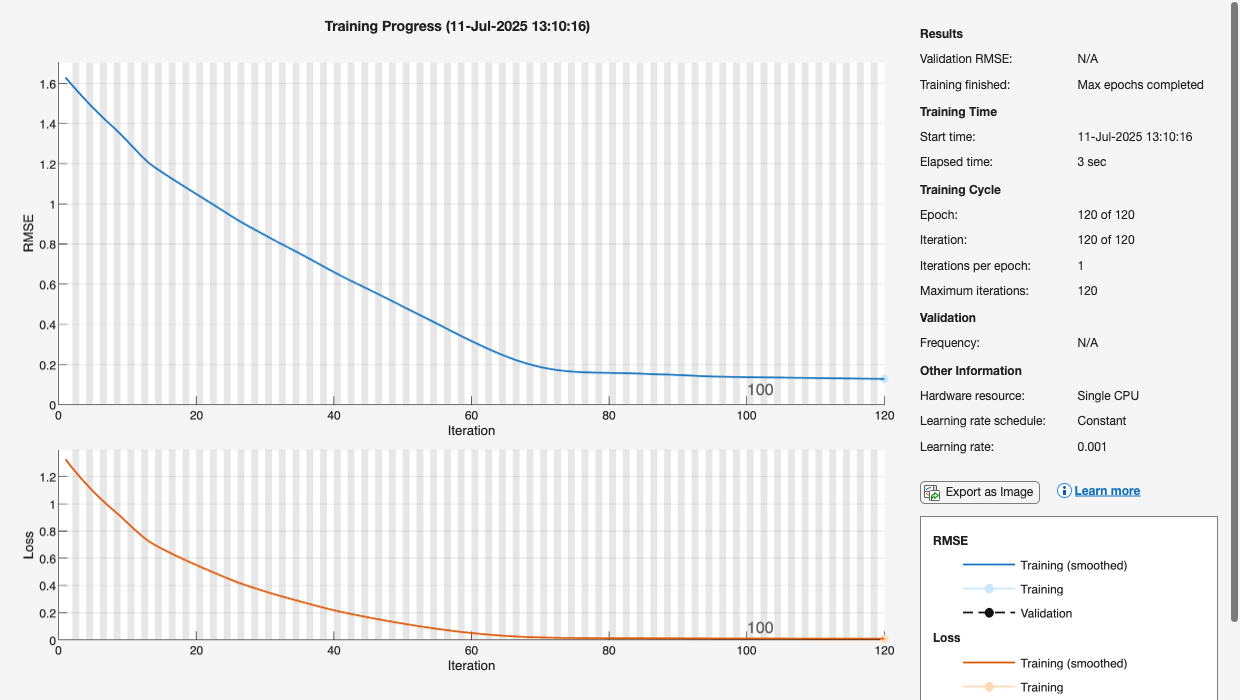

cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'MX201 Vibration Data for analysis.xlsx';
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);

features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];
features = rmmissing(features);  % remove NaNs

X = normalize(features{:,:}, 'range');

%% 20% training split
numTrain = round(0.3 * size(X, 1));
XTrain = {X(1:numTrain, :)'};  
Xseq   = {X'};                         

%% Define network
layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

%% Train
net = trainNetwork(XTrain, XTrain, layers, options);

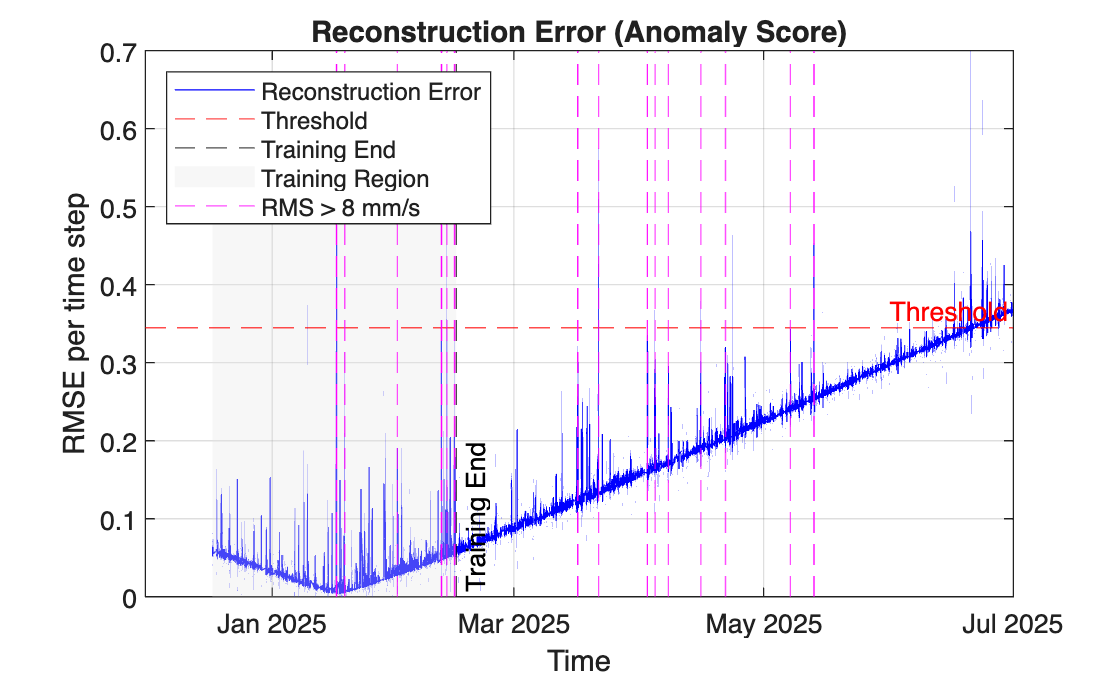


%% Predict
Ypred = predict(net, Xseq);
reconLoss = sqrt(mean((Xseq{1} - Ypred{1}).^2, 1));  
timestamps = data.DateTime(end - numel(reconLoss) + 1:end);

%% Plot
figure;
plot(timestamps, reconLoss, 'b');
hold on;

% Threshold
threshold = prctile(reconLoss, 95);
yline(threshold, '--r', 'Threshold');

% Mark end of training
trainEndTime = data.DateTime(numTrain);
xline(trainEndTime, '--k', 'Training End', 'LabelVerticalAlignment','bottom');

% Shade training region
yl = ylim;
fill([timestamps(1) trainEndTime trainEndTime timestamps(1)], ...
     [yl(1) yl(1) yl(2) yl(2)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.3);  % light gray

% Automatically mark all timestamps where any RMS > 8 mm/s
faultIdx = data.X_RMS > 8 | data.Y_RMS > 8 | data.Z_RMS > 8;
faultTimes = unique(data.DateTime(faultIdx));

for i = 1:numel(faultTimes)
    xline(faultTimes(i), '--m');
end

% Final plot settings
title('Reconstruction Error (Anomaly Score)');
ylabel('RMSE per time step');
xlabel('Time');
legend('Reconstruction Error', 'Threshold', 'Training End', 'Training Region', 'RMS > 8 mm/s', 'Location', 'northwest');
grid on;

% %% --------------------------------------------
% % 📋 Rolling Linear Degradation Forecast – Tabular Output + Threshold Crossing
% % --------------------------------------------
% 
% startIdx = numTrain + 1;
% windowSize = 100;
% 
% % Preallocate results
% resultTimestamps = timestamps(startIdx + windowSize - 1 : end);
% nSteps = length(resultTimestamps);
% degradationFlags = false(nSteps, 1);
% stepsUntilCrossing = NaN(nSteps, 1);
% thresholdCrossed = false(nSteps, 1);
% 
% for i = 1:nSteps
%     t = startIdx + i - 1;
% 
%     HI = reconLoss(t : t + windowSize - 1);
%     tvec = (1:windowSize)';
% 
%     % Record whether threshold is already crossed at this point
%     thresholdCrossed(i) = reconLoss(t + windowSize - 1) > threshold;
% 
%     % Linear fit: HI = m*t + b
%     p = polyfit(tvec, HI, 1);
% 
%     if p(1) > 0  % Degradation (positive slope)
%         % Predict when threshold will be crossed
%         tCross = (threshold - p(2)) / p(1);
%         if isfinite(tCross) && tCross > windowSize
%             degradationFlags(i) = true;
%             stepsUntilCrossing(i) = tCross - windowSize;
%         end
%     end
% end
% 
% % Create final table
% degradationTable = table(resultTimestamps, degradationFlags, ...
%     stepsUntilCrossing, thresholdCrossed, ...
%     'VariableNames', {'Timestamp', 'DegradationDetected', ...
%                       'StepsUntilThresholdCrossing', 'ThresholdCrossed'});
% 
% % Show preview
% crossedRows = degradationTable(degradationTable.ThresholdCrossed, :);
% disp(crossedRows);

         Timestamp          DegradationDetected    StepsUntilThresholdCrossing    ThresholdCrossed
    ____________________    ___________________    ___________________________    ________________

    21-Mar-2025 16:50:40           true                      1205.1                    true       
    13-May-2025 07:24:41           true                      490.93                    true       
    13-May-2025 07:29:41           true                      259.57                    true       
    14-Jun-2025 14:19:36           true                       286.7                    true       
    16-Jun-2025 10:06:31           true                      807.06                    true       
    16-Jun-2025 14:18:36           true                       361.3                    true       
    16-Jun-2025 14:19:36           true                      121.83    

% 

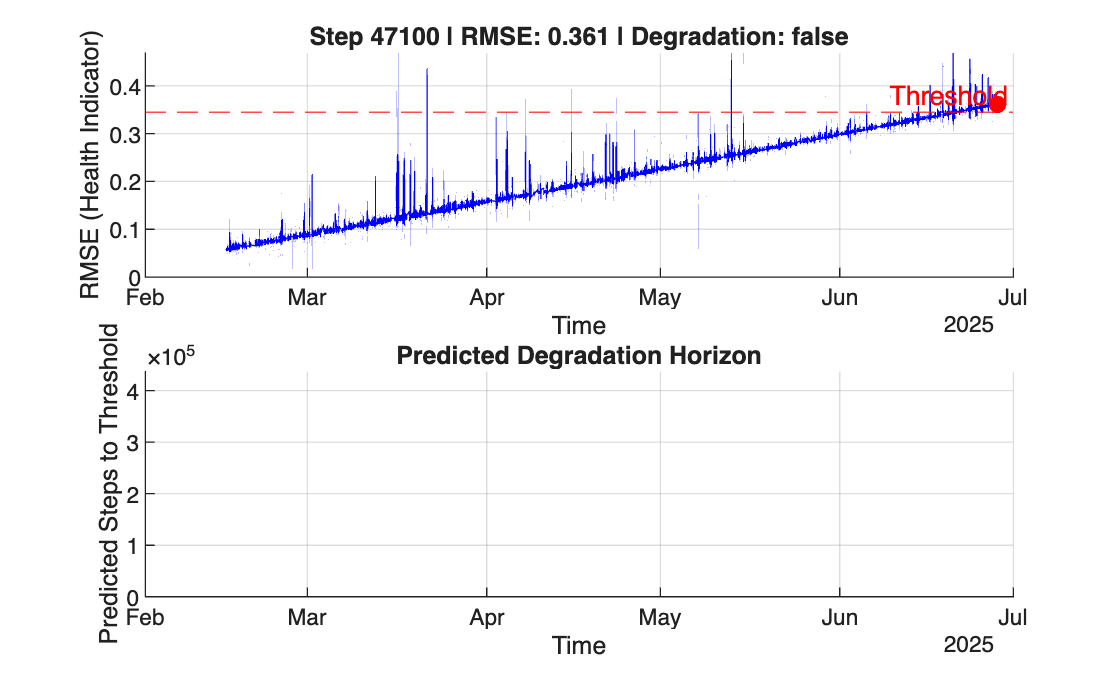

% %% --------------------------------------------
% % 📽️ Animated Rolling Linear RMSE Prediction Plot
% % --------------------------------------------
% 
% figure;
% ax1 = subplot(2,1,1);  % RMSE + fit
% ax2 = subplot(2,1,2);  % Steps until crossing
% 
% % Extract post-training RMSE and time
% trendHI = reconLoss(numTrain+1:end);
% trendTimes = timestamps(numTrain+1:end);
% n = length(trendHI);
% windowSize = 100;
% 
% stepsEst = NaN(n, 1);
% 
% for t = 1:1000:(n - windowSize)
%     HI = trendHI(t : t + windowSize - 1);
%     tvec = (1:windowSize)';
% 
%     % Fit linear model
%     p = polyfit(tvec, HI, 1);
% 
%     % Estimate future crossing
%     stepsLeft = NaN;
%     if p(1) > 0
%         tCross = (threshold - p(2)) / p(1);
%         if isfinite(tCross) && tCross > windowSize
%             stepsLeft = tCross - windowSize;
%             stepsEst(t + windowSize - 1) = stepsLeft;
%         end
%     end
% 
%     % Plot RMSE + window
%     cla(ax1);
%     hold(ax1, 'on');
%     plot(ax1, trendTimes(1:t + windowSize - 1), trendHI(1:t + windowSize - 1), 'b');
%     plot(ax1, trendTimes(t + windowSize - 1), HI(end), 'ro', 'MarkerFaceColor', 'r');
%     yline(ax1, threshold, '--r', 'Threshold');
%     title(ax1, sprintf('Step %d | RMSE: %.3f | Degradation: %s', ...
%         t + windowSize - 1, HI(end), string(p(1) > 0)));
%     ylabel(ax1, 'RMSE (Health Indicator)');
%     xlabel(ax1, 'Time');
%     grid(ax1, 'on');
%     hold(ax1, 'off');
% 
%     % Plot predicted time to threshold
%     cla(ax2);
%     hold(ax2, 'on');
%     plot(ax2, trendTimes(1:t + windowSize - 1), stepsEst(1:t + windowSize - 1), 'k');
%     ylabel(ax2, 'Predicted Steps to Threshold');
%     xlabel(ax2, 'Time');
%     ylim(ax2, [0, max(200, nanmax(stepsEst))]);
%     title(ax2, 'Predicted Degradation Horizon');
%     grid(ax2, 'on');
%     hold(ax2, 'off');
% 
%     pause(0.1);  % Animation speed
% end

%% --------------------------------------------
% 🔁 Rolling ARIMA-Based Degradation Forecast (Tabular)
% --------------------------------------------

startIdx = numTrain + 1;
windowSize = 100;

% Preallocate result storage
resultTimestamps = timestamps(startIdx + windowSize - 1 : end);
nSteps = length(resultTimestamps);
degradationFlags = false(nSteps, 1);
stepsUntilCrossing = NaN(nSteps, 1);
thresholdCrossed = false(nSteps, 1);

for i = 1:nSteps
    t = startIdx + i - 1;

    HI = reconLoss(t : t + windowSize - 1);
    currRMSE = reconLoss(t + windowSize - 1);

    % Record threshold breach
    thresholdCrossed(i) = currRMSE > threshold;

    try
        % Fit ARIMA(1,1,0) model
        model = arima('ARLags',1,'D',1,'Constant',0);
        estModel = estimate(model, HI, 'Display', 'off');
        [forecastedRMSE, ~] = forecast(estModel, 100, 'Y0', HI);

        % Find when forecasted RMSE exceeds threshold
        idxCross = find(forecastedRMSE > threshold, 1);
        if ~isempty(idxCross)
            degradationFlags(i) = true;
            stepsUntilCrossing(i) = idxCross;
        end
    catch
        % Skip this window if ARIMA fails
        continue
    end
end

% Final table with results
degradationTable_ARIMA = table(resultTimestamps, degradationFlags, ...
    stepsUntilCrossing, thresholdCrossed, ...
    'VariableNames', {'Timestamp', 'DegradationDetected', ...
                      'StepsUntilThresholdCrossing', 'ThresholdCrossed'});

% Show a few results
disp(degradationTable_ARIMA(1:10,:));

         Timestamp          DegradationDetected    StepsUntilThresholdCrossing    ThresholdCrossed
    ____________________    ___________________    ___________________________    ________________

    15-Feb-2025 04:40:48           false                       NaN                     false      
    15-Feb-2025 04:45:48           false                       NaN                     false      
    15-Feb-2025 04:50:48           false                       NaN                     false      
    15-Feb-2025 04:55:48           false                       NaN                     false      
    15-Feb-2025 05:00:48           false                       NaN                     false      
    15-Feb-2025 05:05:48           false                       NaN                     false      
    15-Feb-2025 05:10:48           false                       NaN     

degradedRows = degradationTable_ARIMA(degradationTable_ARIMA.DegradationDetected, :);
disp(degradedRows);

    Timestamp    DegradationDetected    StepsUntilThresholdCrossing    ThresholdCrossed
    _________    ___________________    ___________________________    ________________


